% clear all;
% close all
warn = warning ('off','all');

% range, startpoint and target
Xmin=-50;           %range of image
Ymin=-10;
Xmax=50;
Ymax=30;
start_point=[-45 ; 20]; % start point of all nodes
var=5;% point generate variance
wt=[200 ; 20]; % target point location

% coefficients
N=80;      % no. of nodes
dt=0.5;     % time increment / time step
times=120; %Number of iterations
R=3.5;   % neighborhood radius
r=3; % node distance limit
r_min=2;% minimum tolerant distance
d=2; % distance of population from the walls
d_high=3; % distance of population from the walls (green)
chord_threshold=16; % wall width (chord length) change threshold 
x_chord_begin=-25;
x_chord_end=25;
tail_l=1;
dmax=1;

%velocity parameters
lamda=0.5;  
alpha=2;
alpha_max=4;
beta=2;
gamma=2; 
mu=0.5;
Vtar=2.8; %speed of taarget
% Vmax=2.5; %speed of nodes
% Vscale=0; %speed of nodes scaled based on Area

% define wall models
syms P1(z) P2(z)
P1(z)= 0.008*(z-10)^2 +20;%20
P2(z)= -0.008*(z+10)^2 +14;%14
Pd1=diff(P1);% derivative of wall equations
Pd2=diff(P2);
steps1=200;
steps2=steps1;
z1=linspace(Xmin,Xmax,steps1).';
z2=linspace(Xmin,Xmax,steps2).';
yP1=P1(z1);
yP2=P2(z2);
curvexy1=[z1 yP1];
curvexy2=[z2 yP2];
x_fill = [z1.', fliplr(z1.')];
syms y1 x1 y2 x2 cx cy real

% boundaries of wall (red)
syms P1_limit P2_limit
P1_limit(z)= P1(z) -d;
P2_limit(z)= P2(z) +d;
yP1_limit=P1_limit(z1);
yP2_limit=P2_limit(z2);
curvexy_limit1=[z1 yP1_limit];
curvexy_limit2=[z2 yP2_limit];

y_fill_r1 = [yP1.', fliplr(yP1_limit.')];
y_fill_r2 = [yP2.', fliplr(yP2_limit.')];

% boundaries of wall (green)
syms P1_limit_green P2_limit_green
P1_limit_green(z)= P1(z) -d_high;
P2_limit_green(z)= P2(z) +d_high;
yP1_limit_green=P1_limit_green(z1);
yP2_limit_green=P2_limit_green(z2);
curvexy_limit3=[z1 yP1_limit_green];
curvexy_limit4=[z2 yP2_limit_green];

y_fill_g1 = [yP1_limit.', fliplr(yP1_limit_green.')];
y_fill_g2 = [yP2_limit.', fliplr(yP2_limit_green.')];


% directing 
interval=25;
steps_direct=linspace(start_point(1),wt(1),interval).';% x
directx=[steps_direct(2:end-1)];
midpoint=double((P1(directx)+P2(directx))/2); % y
directxy=[directx.'; midpoint.'];
directxy=[directxy,wt];
% directxy=wt;%%%%%%%%%%%%%%%%%%%%%
directx=directxy(1,:);
directy=directxy(2,:);

% generating the initial population (distributed in acircle with radius 'var')
x=zeros(2,N,times+1); % location of all nodes (uniformly distribute in a circle with radius var)
rng(2);
radius = var*sqrt(rand(1,N)); % Using square root here ensures distribution uniformity by area
rng(3);
t = 2*pi*rand(1,N);
x_cor = radius.*cos(t);
y_cor = radius.*sin(t);
x(:,:,1)=[start_point(1)+x_cor;start_point(2)+y_cor];
x(:,:,2)=[start_point(1)+x_cor;start_point(2)+y_cor];

% define all variables
u=zeros(2,N,times+1); % velocity of all nodes
ua=zeros(2,N,times+1); % heading target velocity of all nodes
ub=zeros(2,N,times+1);% reunion velocity
uc=zeros(2,N,times+1); % coherent motion velocity
delta=zeros(2,N,times+1);
ug=zeros(2,N,times); % gravity center velocity
dist=zeros(N,times); % distance from each node to target
phi=zeros(2,N,times+1);
flag_edge=zeros(N,times);
chord_length=zeros(N,times);
chord_centre=zeros(2,N,times);
r_change=r*ones(N,times);
targetxy=zeros(2,N,times);
alpha_change=alpha*ones(N,times+1);
vind_all_include=cell(N);
tailxy=zeros(2,N,times+1);
umean=zeros(1,times);
rmean_k=zeros(N,times);
rmean=zeros(1,times);

% initialize velocity 
u(:,:,2)=(wt-x(:,:,1))./vecnorm(wt-x(:,:,1));
umean(1)=mean(vecnorm(u(:,:,2)),2);
targetxy(:,:,2)=repmat(directxy(:,1),1,N);

% at time t, location is updated by u(:,k,t+1)
for t=2:times 

    dist(:,t)=vecnorm(targetxy(:,:,t)-x(:,:,t)).'; % dist between each node and target
    dist_nodek=zeros(N,N); % distance between every two nodes (l,k)

    % distance from node to the closer wall
    pointsxy=x(:,:,t).';
    [xy1,distances1,~] = distance2curve(curvexy1,pointsxy,'linear');
    [xy2,distances2,~] = distance2curve(curvexy2,pointsxy,'linear');
    wallpoints1=xy1.';
    wallpoints2=xy2.';
    
    for k=1:N
        % solve chord problem
        if x(1,k,t) > x_chord_begin && x(1,k,t)< x_chord_end
            % equations and conditions of solving chord problem
            y1=P1(x1);
            y2=P2(x2);
            eqns=[(y1-cy)*Pd1(x1)==-(x1-cx), (y2-cy)*Pd2(x2)==-(x2-cx)...
                (x1-cx)^2+(y1-cy)^2==(x2-cx)^2+(y2-cy)^2, (y1-x(2,k,t))*(x2-x(1,k,t))==(y2-x(2,k,t))*(x1-x(1,k,t))];
            [p1_x, p2_x, centre_x, centre_y] = vpasolve(eqns,[x1 x2 cx cy]);       
            p1_y=P1(p1_x);
            p2_y=P2(p2_x);
            p1=[p1_x.'; p1_y.'];
            p2=[p2_x.'; p2_y.'];
            % filter (identify right solution manually)
            chord_length_all=vecnorm(double(p1-p2));
            [chord,chord_ind]=min(chord_length_all);
            chord_length(k,t)=chord;
            % update the adaptive safe diatance and velocity parameter alpha
            if chord_length(k,t) < chord_threshold
                r_change(k,t)=r_min+(r-r_min)*(1-(chord_threshold-chord_length(k,t))/chord_threshold);
                alpha_change(k,t+1)=alpha+(alpha_max-alpha)*(chord_threshold-chord_length(k,t))/chord_threshold;
            end
        end

        % update neighbourhood
        dist_nodek(:,k)=vecnorm(x(:,:,t)-x(:,k,t)).'; % distance between k and its neighbour
        vind=find(dist_nodek(:,k)<=R & dist_nodek(:,k)>0); % index of neighbourhood (doesn't include itself)
        vind_all_include{k}=find(dist_nodek(:,k)<=R); % index of  neighbourhood (include itself)
        vind_nonneigh=find(dist_nodek(:,k)>R);% index of outside neighbourhood 
        Nk=length(vind_all_include{k}); % number of neighbours of k

        % update rk mean
        rmean_k(k,t-1)=mean(dist_nodek(vind,k),1);

        % update heading target velocity / avoid collision velocity
            ua_raw=[];
             if distances1(k)<=d
                ua_raw=[ua_raw 2*(d/distances1(k)-1)*(x(:,k,t)-wallpoints1(:,k))];
            end
            if distances2(k)<=d
                ua_raw=[ua_raw 2*(d/distances2(k)-1)*(x(:,k,t)-wallpoints2(:,k))];
            end
            ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))./dist(k,t)];
            ua(:,k,t+1)=mean(ua_raw,2);

        % update gravity center velocity
        ug(:,k,t)=mean(phi(:,vind_all_include{k},t),2);

        % reunion 
        % decide which edge
        W=[u(1,k,t)/norm(u(:,k,t)) -u(2,k,t)/norm(u(:,k,t)); u(2,k,t)/norm(u(:,k,t)) u(1,k,t)/norm(u(1,k,t))]; 
        xlk=zeros(2,N);
        for l=vind  % just care about neighbor fish
            xlk(:,l)=W'*(x(:,l,t)-x(:,k,t)); % (W times every relative location of fish k)
        end
        if xlk(1,:)==-abs(xlk(1,:)) % (all negative, no node l lies in the front of k) k is at front
           flag_edge(k,t)=1;
        elseif xlk(2,:)==abs(xlk(2,:)) % (all positive, all nodes l lie in left of node k) l(s) are all at left, k is at right edge
           flag_edge(k,t)=2;
        elseif xlk(2,:)==-abs(xlk(2,:)) % l(s) are all at right, k is at left edge
           flag_edge(k,t)=3;
        else 
           flag_edge(k,t)=0;
        end
       
        % update coherent motion velocity (avoid collisions)
        if Nk > 1
                delta(:,k,t)=(1/(Nk-1)) * sum((1-r_change(k,t)./dist_nodek(vind,k)).' .*  (x(:,vind,t)-x(:,k,t)),2); 
        end
        uc(:,k,t+1)=(1-lamda)*ug(:,k,t)+gamma*delta(:,k,t);
        
        % update velocity of each node 
        u(:,k,t+1)=lamda*(alpha_change(k,t+1)*ua(:,k,t+1)+beta*ub(:,k,t))+uc(:,k,t+1);

        % update location
        x(:,k,t+1)=x(:,k,t)+dt*u(:,k,t+1);

        % dont go out
        if x(2,k,t+1) >= P1(x(1,k,t+1)) || x(2,k,t+1) <= P2(x(1,k,t+1))
            x(:,k,t+1)=x(:,k,t);
            u(:,k,t+1)=[0;0];
        end
        

        % update phi (local center of gravity velocity elements)
        phi(:,k,t+1)=(1-mu)*ug(:,k,t)+mu*u(:,k,t+1);
    end
    % update v measurement
    umean(t)=mean(vecnorm(u(:,:,t+1)),2);
    % update r measurement
    rmean(t-1)=mean(rmean_k(:,t-1));

    % tail generation
    % unit velocity
    u_mag=repmat(vecnorm(u(:,:,t+1)),2,1);
    u_unit=u(:,:,t+1)./u_mag;
    % tail point
    tailxy(:,:,t)=x(:,:,t)-tail_l*u_unit;

    % set reunion velocity
    % find the nearest edge (different from itself)
    for k=1:N
        flag_out_neigh=flag_edge(:,t);
        flag_out_neigh(vind_all_include{k})=0;% flag for nodes outside the neighbour of node k
        if flag_edge(k,t)==1 % front
           tb =find(flag_out_neigh == 1); % the index of same edges
           if length(tb) == 0
               ub(:,k,t+1)=zeros(2,1);
           else
               dist_kl=dist_nodek(tb,k);    
               [~, ind]= min(dist_kl);
               l=tb(ind);
               ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
           end
       
        elseif flag_edge(k,t)==2 % right
           tb =find(flag_out_neigh == 2); % the index of same edges
           if length(tb) == 0
               ub(:,k,t+1)=zeros(2,1);
           else
               dist_kl=dist_nodek(tb,k);    
               [~, ind]= min(dist_kl);
               l=tb(ind);
               ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
           end

        elseif flag_edge(k,t)==3 % left
           tb =find(flag_out_neigh == 3); % the index of same edges
           if length(tb) == 0
               ub(:,k,t+1)=zeros(2,1);
           else
               dist_kl=dist_nodek(tb,k);    
               [~, ind]= min(dist_kl);
               l=tb(ind);
               ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
           end
        else 
            ub(:,k,t+1)=zeros(2,1);
        end
    end 

    % update target
    tind=find(directx>(targetxy(1,1,t)+Vtar),1);% find the next directing point
    targetxy(:,:,t+1)=targetxy(:,:,t)+(dt*Vtar*(directxy(:,tind)-targetxy(:,1,t))/vecnorm(directxy(:,tind)-targetxy(:,1,t)));

    t
end

t = 2

t = 3

t = 4

t = 5

t = 6

t = 7

t = 8

t = 9

t = 10

t = 11

t = 12

t = 13

t = 14

t = 15

t = 16

t = 17

t = 18


% gennerate tail matrix
tail_draw=zeros(2,3*N,times);
for t=1:times
    for k=1:N
        tail_draw(:,3*(k-1)+1,t)=x(:,k,t);
        tail_draw(:,3*(k-1)+2,t)=tailxy(:,k,t);
        tail_draw(:,3*(k-1)+3,t)=[NaN;NaN];
    end
end
Xtail=squeeze(tail_draw(1,:,:));
Ytail=squeeze(tail_draw(2,:,:));

% save('bigdata.mat', 'x','u','alpha_change','r_change',"Xtail","Ytail","umean","rmean","targetxy"); % Saves specific variables

% plot video
for t = 2 : times
    t
    figure('Visible', 'off');
    hold on;
    % walls
    plot(curvexy1(:,1),curvexy1(:,2),'k')
    plot(curvexy2(:,1),curvexy2(:,2),'k')
    % wall boundary 
    plot(curvexy_limit1(:,1),curvexy_limit1(:,2),'r','MarkerSize',2)
    plot(curvexy_limit2(:,1),curvexy_limit2(:,2),'r','MarkerSize',2)
%     plot(curvexy_limit3(:,1),curvexy_limit3(:,2),'Color',[0 1 0.5],'MarkerSize',2)
%     plot(curvexy_limit4(:,1),curvexy_limit4(:,2),'Color',[0 1 0.5],'MarkerSize',2)
    % nodes
    scatter(x(1,:,t),x(2,:,t),60,'.','b');
    % tail
    plot(Xtail(:,t), Ytail(:,t), '-b');
    % fill
    fill(x_fill, y_fill_r1, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill(x_fill, y_fill_r2, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
%     fill(x_fill, y_fill_g1, 'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
%     fill(x_fill, y_fill_g2, 'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    % target(guide)
    fill([targetxy(1,1,t)-0.5,targetxy(1,1,t)+0.5,targetxy(1,1,t)+0.5,targetxy(1,1,t)-0.5], [targetxy(2,1,t)-0.5,targetxy(2,1,t)-0.5,targetxy(2,1,t)+0.5,targetxy(2,1,t)+0.5], 'r', 'EdgeColor', 'none')
    % start and end points
    scatter(wt(1),wt(2),'*','r');
    scatter(start_point(1),start_point(2),'*','black')
    % axis (xy limit)
    axis([Xmin Xmax Ymin Ymax]);
    axis equal
    hold off;

    drawnow
    ax = gca;
    ax.Units = 'pixels';
    pos = ax.Position;
    marg = 30;
    rect = [-marg, -marg, pos(3)+2*marg, pos(4)+2*marg];
    M(t-1) = getframe(gca,rect);
    ax.Units = 'normalized';
end

t = 2

t = 3

t = 4

t = 5

t = 6

t = 7

t = 8

t = 9

t = 10

t = 11

t = 12

t = 13

t = 14

t = 15

t = 16

t = 17

t = 18

t = 19

t = 20

t = 21

t = 22

t = 23

t = 24

t = 25

t = 26

t = 27

t = 28

t = 29

t = 30

t = 31

t = 32

t = 33

t = 34

t = 35

t = 36

t = 37

t = 38

t = 39

t = 40

t = 41

t = 42

t = 43

t = 44

t = 45

t = 46

t = 47

t = 48

t = 49

t = 50

t = 51

t = 52

t = 53

t = 54

t = 55

t = 56

t = 57

t = 58

t = 59

t = 60

t = 61

t = 62

t = 63

t = 64

t = 65

t = 66

t = 67

t = 68

t = 69

t = 70

t = 71

t = 72

t = 73

t = 74

t = 75

t = 76

t = 77

t = 78

t = 79

t = 80

t = 81

t = 82

t = 83

t = 84

t = 85

t = 86

t = 87

t = 88

t = 89

t = 90

t = 91

t = 92

t = 93

t = 94

t = 95

t = 96

t = 97

t = 98

t = 99

t = 100

t = 101

t = 102

t = 103

t = 104

t = 105

t = 106

t = 107

t = 108

t = 109

t = 110

t = 111

t = 112

t = 113

t = 114

t = 115

t = 116

t = 117

t = 118

t = 119

t = 120


myVideo = VideoWriter('passage_noadapt.avi');
open(myVideo);
writeVideo(myVideo, M);
close(myVideo);

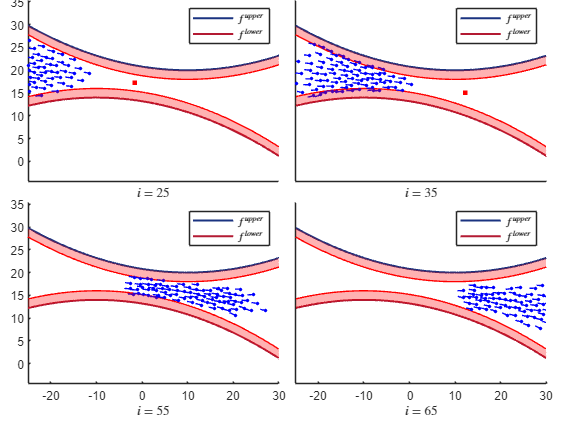

% plot figures
close all;
i=1;
ha = tight_subplot(2,2,[.05 .03],[.09 .00],[.05 .03]); % Adjusts the gaps
figure;
% plot
for t = [26,36,56,66]
    axes(ha(i));
    % Enable x-ticks and y-ticks
    set(ha(i), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
    set(ha(i), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
    hold on;
    % walls
    pp1=plot(curvexy1(:,1),curvexy1(:,2),'k','LineWidth',1.5,Color=[0.1 0.2 0.5]);
    pp2=plot(curvexy2(:,1),curvexy2(:,2),'k','LineWidth',1.5,Color=[0.7 0.1 0.2]);
    % wall boundary 
    plot(curvexy_limit1(:,1),curvexy_limit1(:,2),'r','MarkerSize',2)
    plot(curvexy_limit2(:,1),curvexy_limit2(:,2),'r','MarkerSize',2)
    % nodes
    scatter(x(1,:,t),x(2,:,t),60,'.','b');
    % tail
    plot(Xtail(:,t), Ytail(:,t), '-b');
    % fill
    fill(x_fill, y_fill_r1, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill(x_fill, y_fill_r2, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
%     fill(x_fill, y_fill_g1, 'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
%     fill(x_fill, y_fill_g2, 'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    % target(guide)
    fill([targetxy(1,1,t)-0.5,targetxy(1,1,t)+0.5,targetxy(1,1,t)+0.5,targetxy(1,1,t)-0.5], [targetxy(2,1,t)-0.5,targetxy(2,1,t)-0.5,targetxy(2,1,t)+0.5,targetxy(2,1,t)+0.5], 'r', 'EdgeColor', 'none')
    % start and end points
    scatter(wt(1),wt(2),'*','r');
%     scatter(start_point(1),start_point(2),'*','black')
    % axis (xy limit)
    axis([-25 30 5 Ymax]);
%     xlim([-25 25])
%     ylim([-10 10])
    axis equal

    if mod(i,2) == 0
        yticks([]);
    end
    if i < 3
        xticks([]);
    end
    xlabel(['$i=$' num2str(t-1)],Interpreter = 'latex')
    hold off;
    i=i+1;
    lgd=legend([pp1,pp2],'$f^{ upper}$','$f^{ lower}$');
    lgd.Interpreter = 'latex';  % Using TeX interpreter for formatting
end

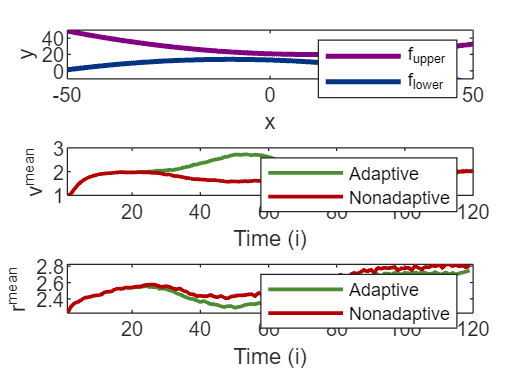

% v measurement
figure;
subplot(3,1,1)
% walls
plot(curvexy1(:,1),curvexy1(:,2),'LineWidth', 2, Color=[0.5, 0, 0.5])
hold on
plot(curvexy2(:,1),curvexy2(:,2),'LineWidth', 2, Color=[0, 0.2, 0.5])
legend('f_{upper}','f_{lower}')
hold off
axis([Xmin Xmax Ymin 50]);
xlabel('x')
ylabel('y')

subplot(3,1,2)
plot(umean,'LineWidth', 1.5, Color=[0.3, 0.55, 0.2])
hold on
plot(umean_noadapt,'LineWidth', 1.5, Color=[0.7, 0, 0])
xlim([1 times])
legend('Adaptive','Nonadaptive','Location','southeast')
xlabel('Time (i)')
ylabel('v^{mean}')

subplot(3,1,3)
plot(rmean(1:end-1),'LineWidth', 1.5,Color=[0.3, 0.55, 0.2])
hold on
plot(rmean_noadapt(1:end-1),'LineWidth', 1.5, Color=[0.7, 0, 0])
xlim([1 times])
legend('Adaptive','Nonadaptive','Location','southeast')
xlabel('Time (i)')
ylabel('r^{mean}')

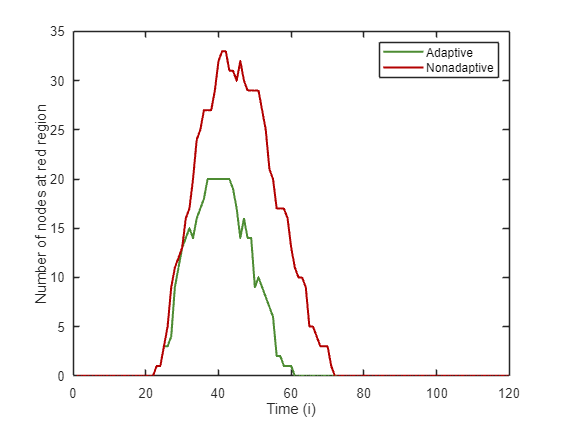

% COLLISION NODES
load ('bigdata.mat')
outnondes=zeros(1,times);
outnondes_noadapte=zeros(1,times);
for t=2:times+1
    upper=x(2,:,t) - P1_limit(x(1,:,t));
    lower=x(2,:,t) - P2_limit(x(1,:,t));
    outnondes(t-1)=length(upper(upper>0))+length(lower(lower<0));
    upper=x_noadapt(2,:,t) - P1_limit(x(1,:,t));
    lower=x_noadapt(2,:,t) - P2_limit(x(1,:,t));
    outnondes_noadapte(t-1)=length(upper(upper>0))+length(lower(lower<0));
end
figure
plot(outnondes,'LineWidth', 1.5, Color=[0.3, 0.55, 0.2])
hold on
plot(outnondes_noadapte,'LineWidth', 1.5, Color=[0.7, 0, 0])
legend('Adaptive','Nonadaptive')
xlabel('Time (i)')
ylabel('Number of nodes at red region')

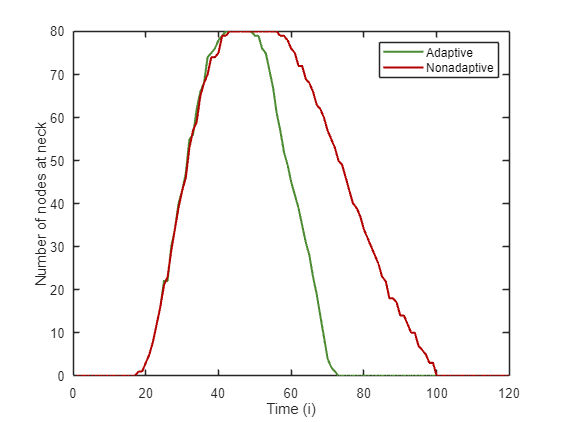

% NECK NODES
times=120;
necknondes=zeros(1,times);
necknondes_noadapte=zeros(1,times);
neckstart=-20;
neckend=20;
for t=2:times+1
    necknondes(t-1)=length(find(x(1,:,t)>neckstart & x(1,:,t)<neckend));
    necknondes_noadapte(t-1)=length(find(x_noadapt(1,:,t)>neckstart & x_noadapt(1,:,t)<neckend));
end
figure
plot(necknondes,'LineWidth', 1.5, Color=[0.3, 0.55, 0.2])
hold on
plot(necknondes_noadapte,'LineWidth', 1.5, Color=[0.7, 0, 0])
legend('Adaptive','Nonadaptive')
xlabel('Time (i)')
ylabel('Number of nodes at neck')

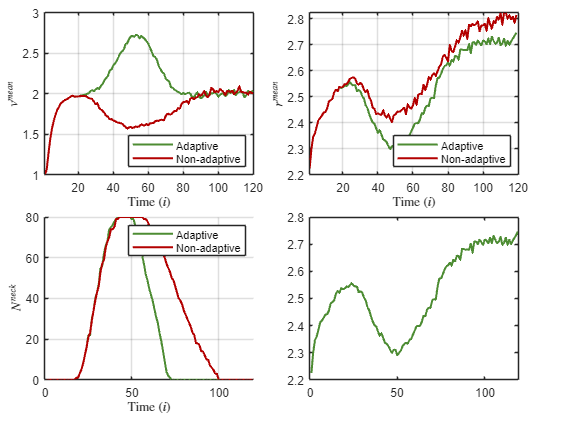

% Combined Figures
close all;

ha = tight_subplot(2,2,[.1 .1],[.1 .03],[.08 .08]); % Adjusts the gaps
figure;

axes(ha(1));
set(ha(1), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(ha(1), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
plot(umean,'LineWidth', 1.5, Color=[0.3, 0.55, 0.2])
hold on
plot(umean_noadapt,'LineWidth', 1.5, Color=[0.7, 0, 0])
xlim([1 times])
legend('Adaptive','Non-adaptive','Location','southeast')
xlabel('Time ($i$)',Interpreter='latex')
ylabel('$v^{mean}$',Interpreter='latex')
hold off
grid on

axes(ha(2));
set(ha(2), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(ha(2), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
plot(rmean(1:end-1),'LineWidth', 1.5,Color=[0.3, 0.55, 0.2])
hold on
plot(rmean_noadapt(1:end-1),'LineWidth', 1.5, Color=[0.7, 0, 0])
xlim([1 times])
legend('Adaptive','Non-adaptive','Location','southeast')
xlabel('Time ($i$)',Interpreter='latex')
ylabel('$r^{mean}$',Interpreter='latex')
hold off
grid on

axes(ha(3));
set(ha(3), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(ha(3), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
hold on
plot(necknondes,'LineWidth', 1.5, Color=[0.3, 0.55, 0.2])
plot(necknondes_noadapte,'LineWidth', 1.5, Color=[0.7, 0, 0])
legend('Adaptive','Non-adaptive')
xlabel('Time ($i$)',Interpreter='latex')
ylabel('$N^{neck}$',Interpreter='latex')
hold off
grid on

axes(ha(4));
set(ha(4), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(ha(4), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
plot(rmean(1:end-1),'LineWidth', 1.5,Color=[0.3, 0.55, 0.2])

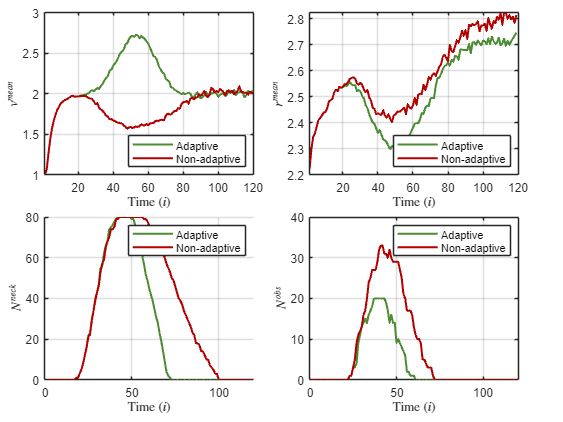

plot(outnondes,'LineWidth', 1.5, Color=[0.3, 0.55, 0.2])
hold on
plot(outnondes_noadapte,'LineWidth', 1.5, Color=[0.7, 0, 0])
legend('Adaptive','Non-adaptive')
xlabel('Time ($i$)',Interpreter='latex')
ylabel('$N^{obs}$',Interpreter='latex')
hold off
grid on